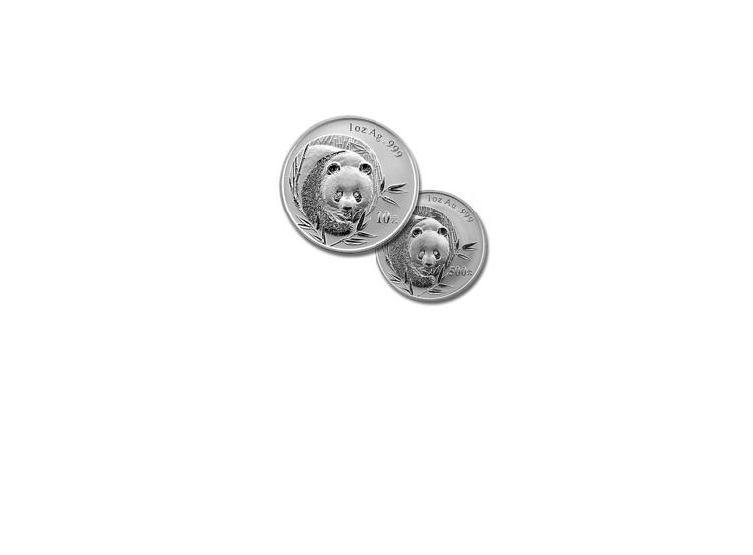

%EXERCICI 2

%IMATGE 2
im1 = im2gray(im2double(imread('coins1.jpg')));
imshow(im1);

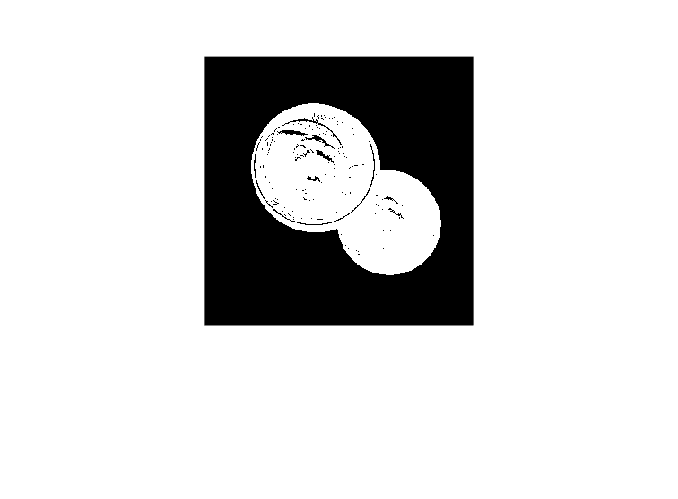


%binarització
y = im1 < 0.9;
imshow(y)

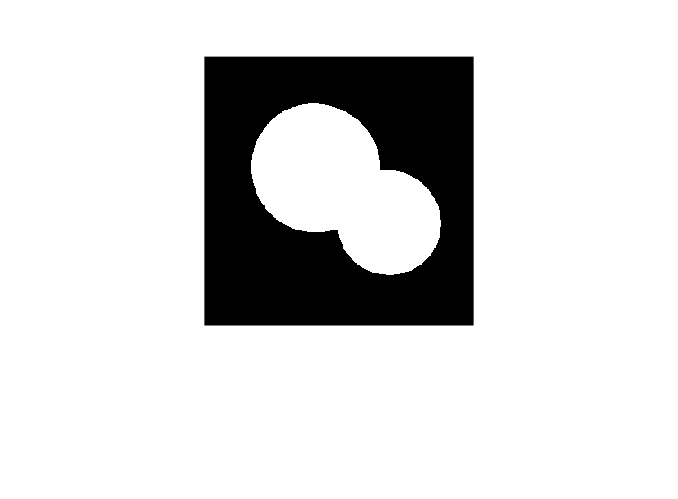


%Tapem els forats amb un closing
se = ones(6,6);
closing = imerode(imdilate(y,se),se);
imshow(closing)

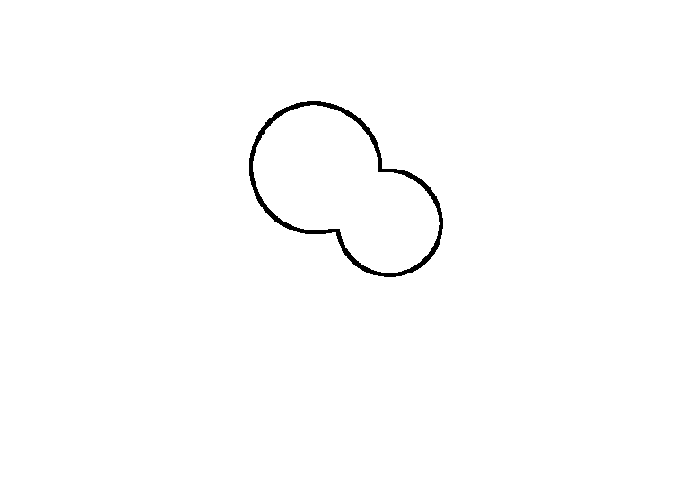


%Distancia del pixel al edge més proper
%Calculem primer l'edge
se = ones(5,5);
edge = imdilate(closing,se) - imerode(closing,se);
%Fem ara la distancia
dist = bwdist(edge);
imshow(dist);

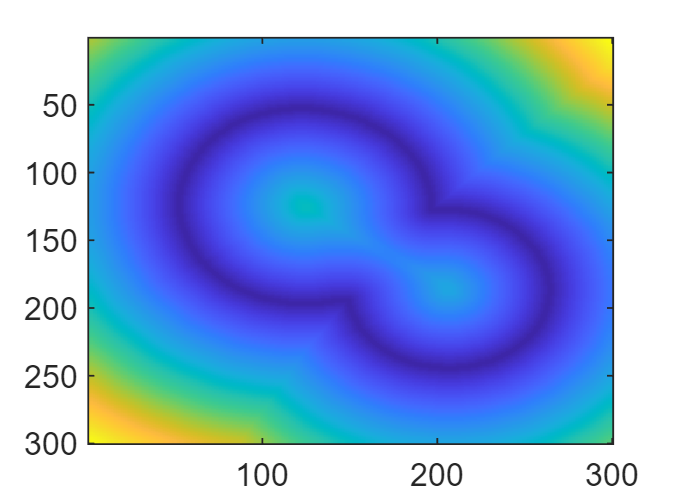


%Apliquem una dilatació (5,5)
se = ones(5,5);
dilatacio = imdilate(dist,se);
imagesc(dilatacio);

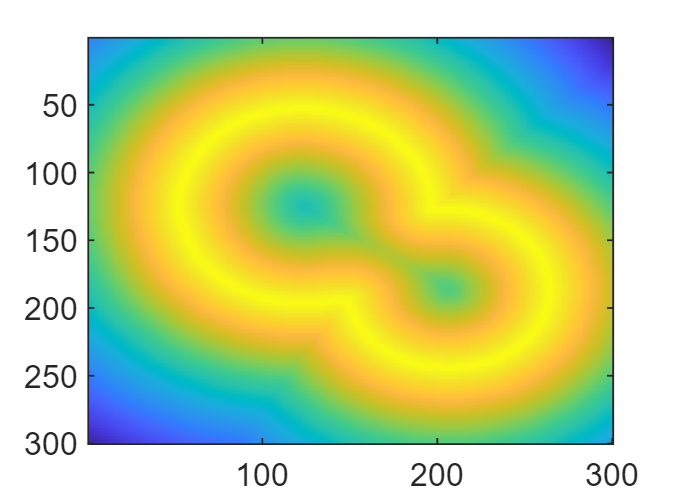


%Fem la inversa i apliquem watersheed. 
inv = 1 - dilatacio;
imagesc(inv);

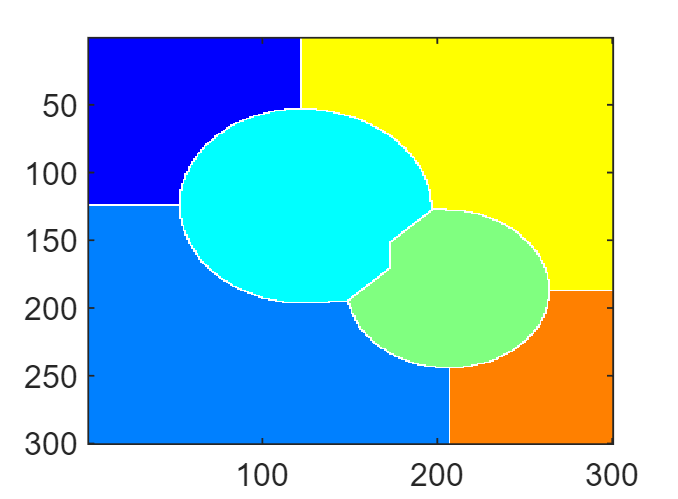

y = watershed(inv,8);
color = im2double(label2rgb(y));
imagesc(color);

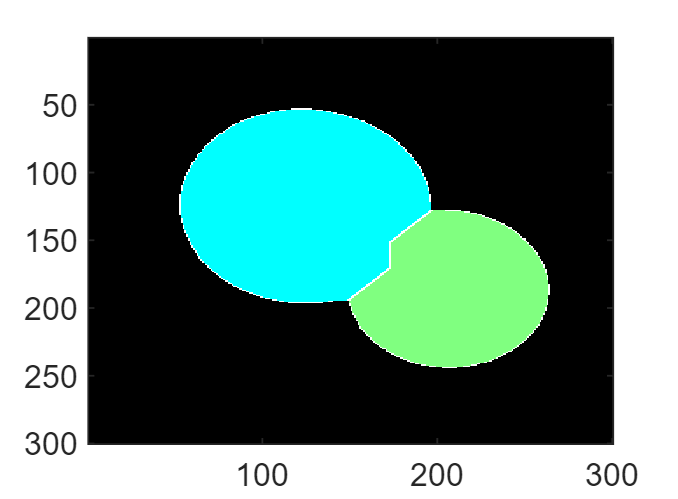


%Restringim el resultat als objectes d'interès
im1_final = closing.*color;
imagesc(im1_final);

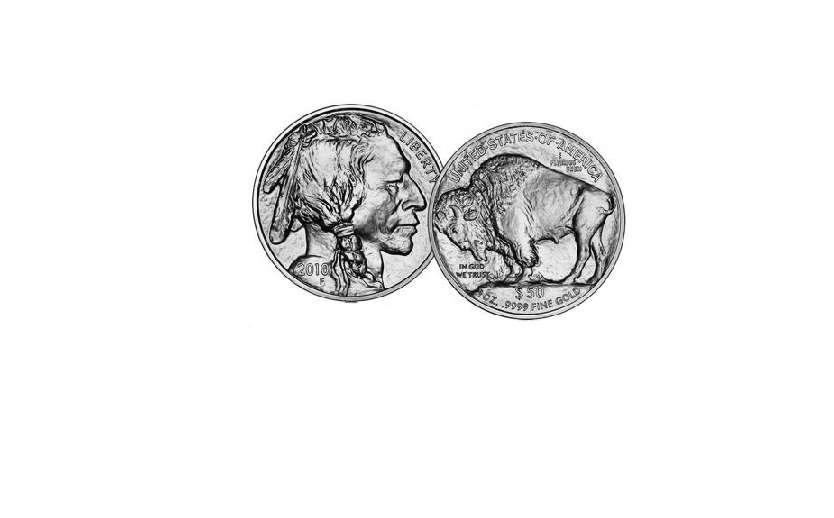


%Contem les monedes que hem segmentat



%IMATGE 2
im2 = im2gray(im2double(imread('coins2.jpg')));
imshow(im2);

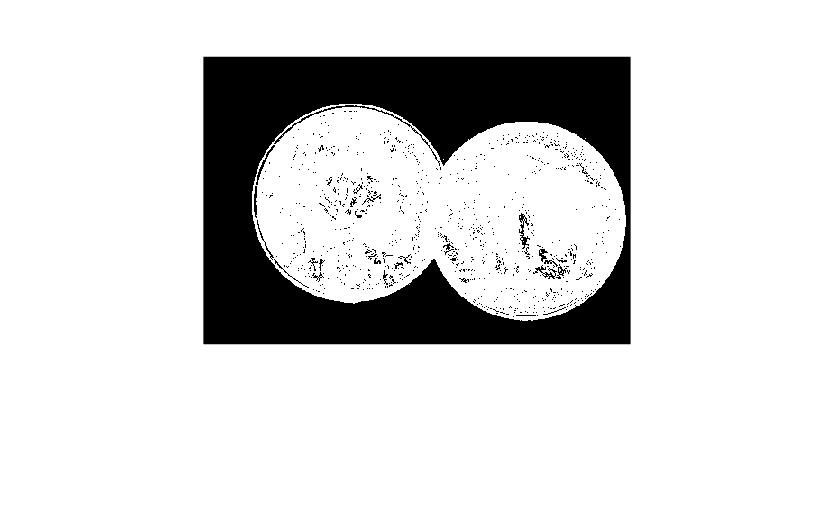


%binarització
y = im2 < 0.9;
imshow(y)

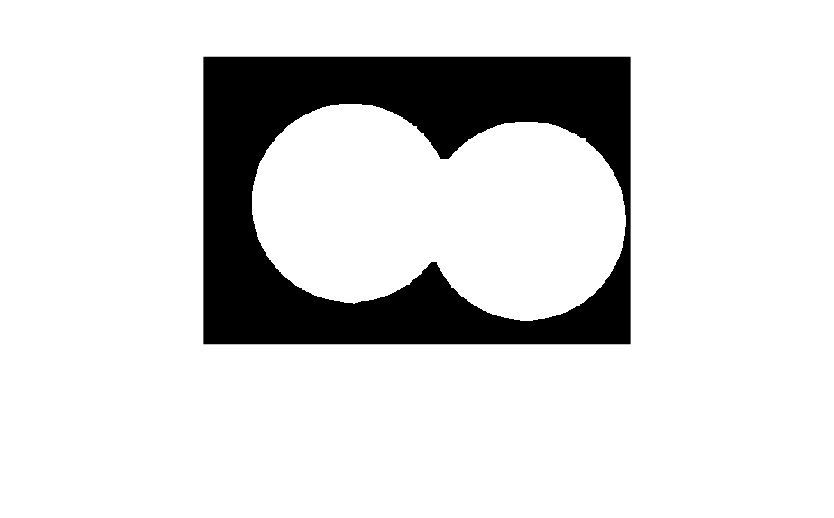


%Tapem els forats amb un closing
se = ones(6,6);
closing = imerode(imdilate(y,se),se);
imshow(closing)

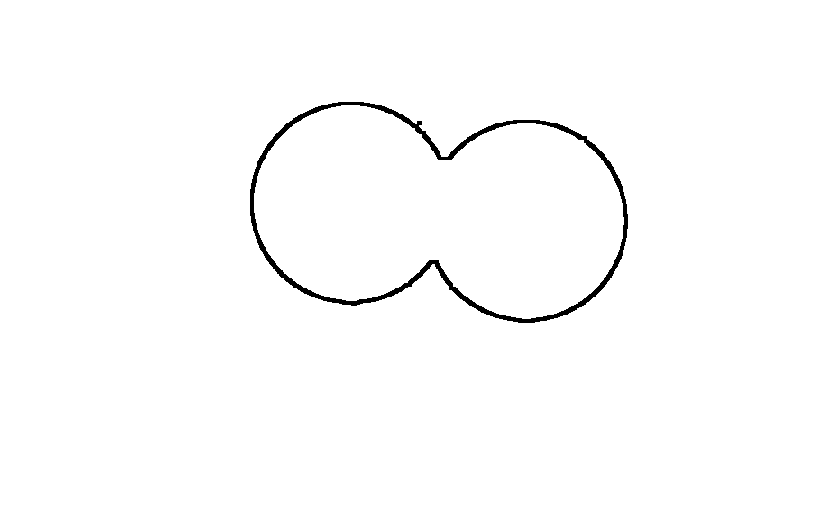


%Distancia del pixel al edge més proper
%Calculem primer l'edge
se = ones(5,5);
edge = imdilate(closing,se) - imerode(closing,se);
%Fem ara la distancia
dist = bwdist(edge);
imshow(dist);

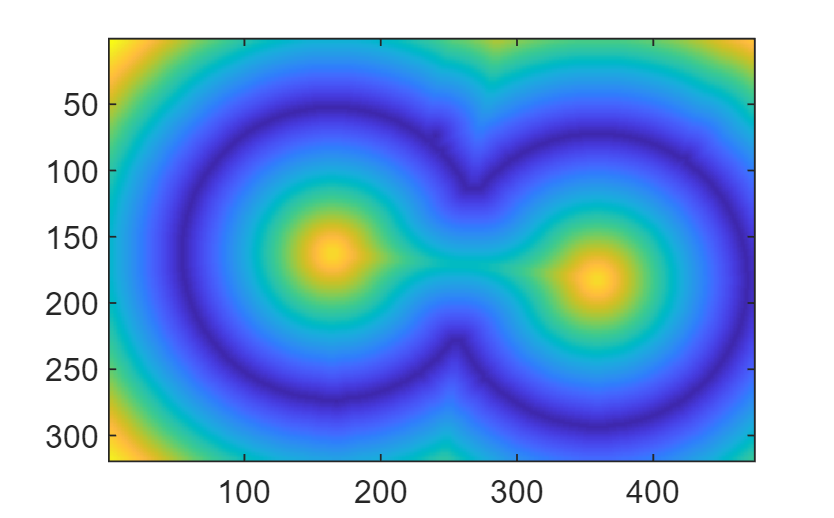


%Apliquem una dilatació (5,5)
se = ones(5,5);
dilatacio = imdilate(dist,se);
imagesc(dilatacio);

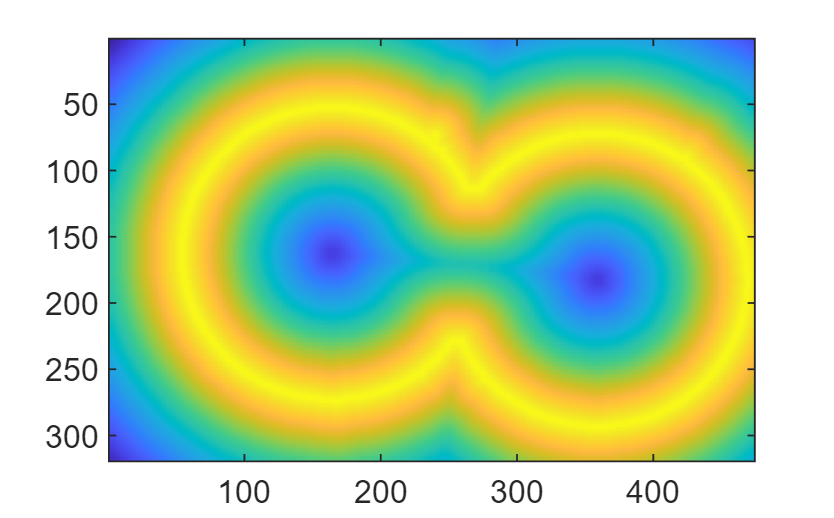


%Fem la inversa i apliquem watersheed. 
inv = 1 - dilatacio;
imagesc(inv);

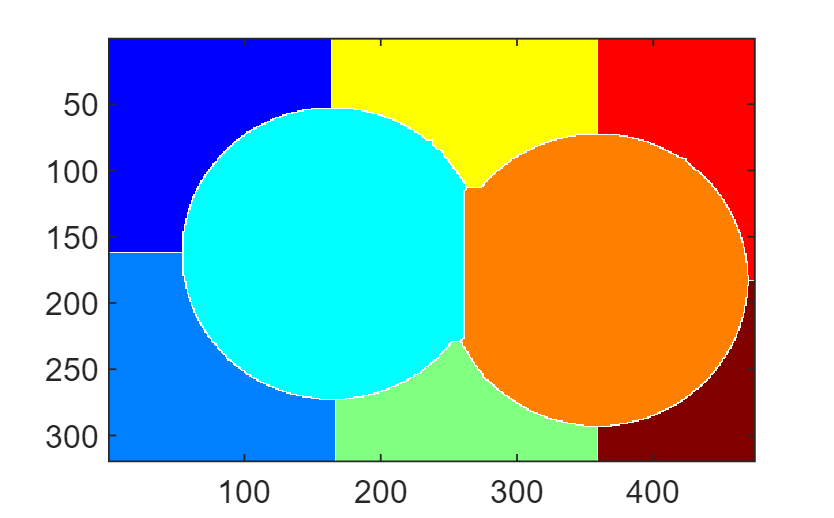

y = watershed(inv,8);
color = im2double(label2rgb(y));
imagesc(color);

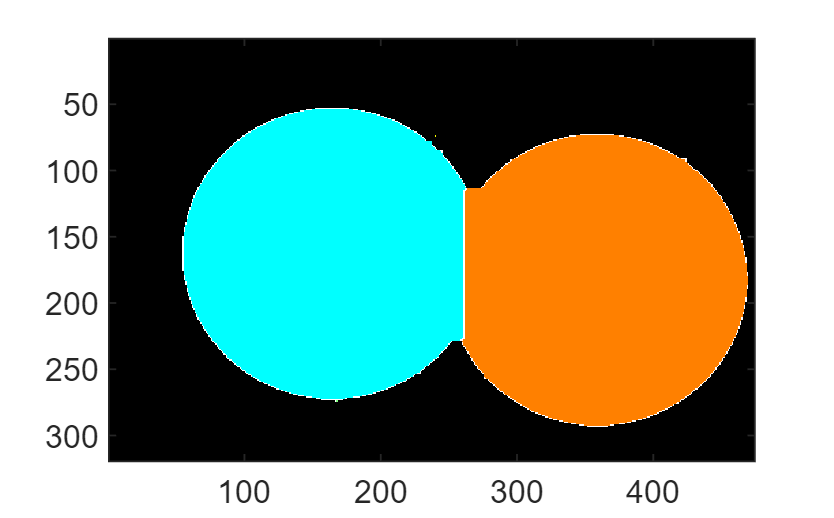


%Restringim el resultat als objectes d'interès
im2_final = closing.*color;
imagesc(im2_final);

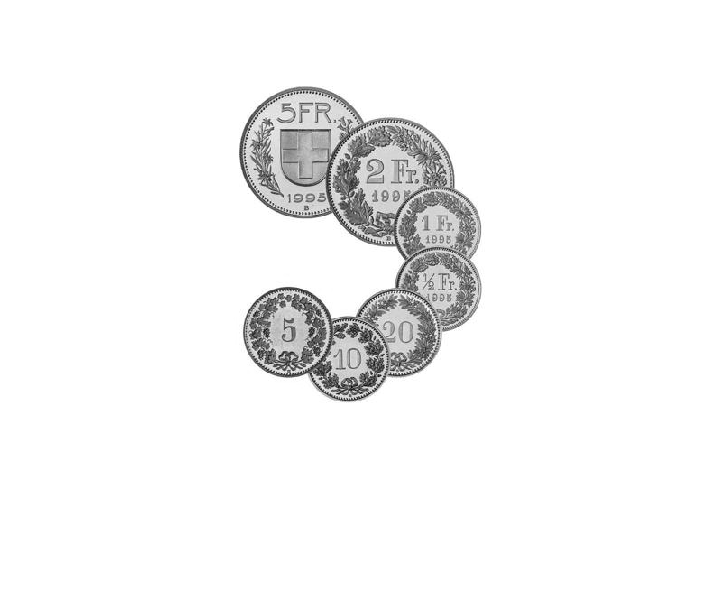

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.




%Contem les monedes que hem segmentat




%IMATGE 5
im5 = im2gray(im2double(imread('coins5.jpg')));
imshow(im5);

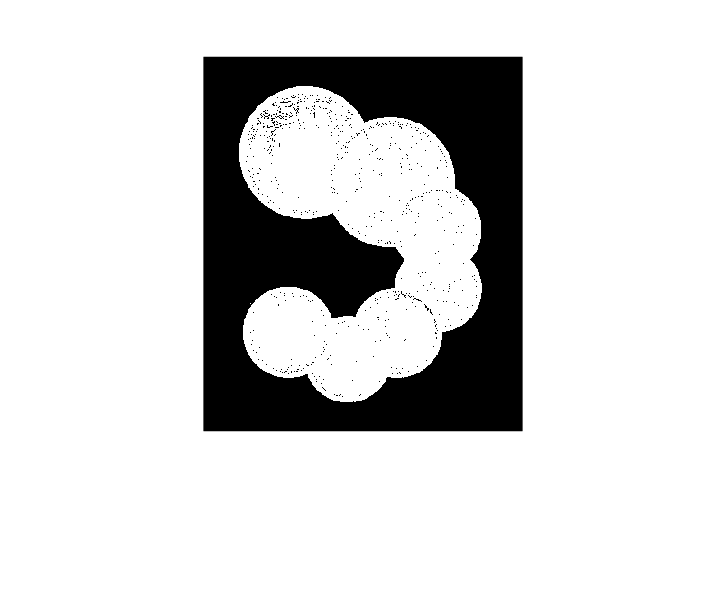


%binarització
y = im5 < 0.9;
imshow(y)

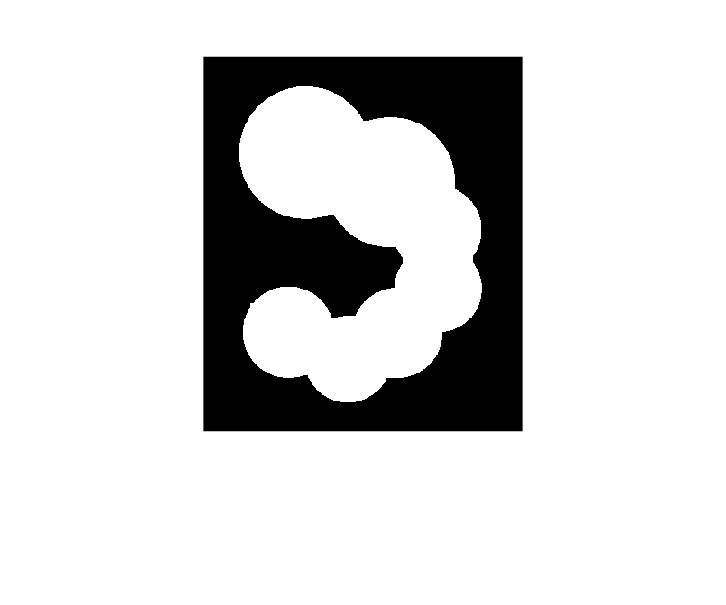


%Tapem els forats amb un closing
se = ones(6,6);
closing = imerode(imdilate(y,se),se);
imshow(closing)

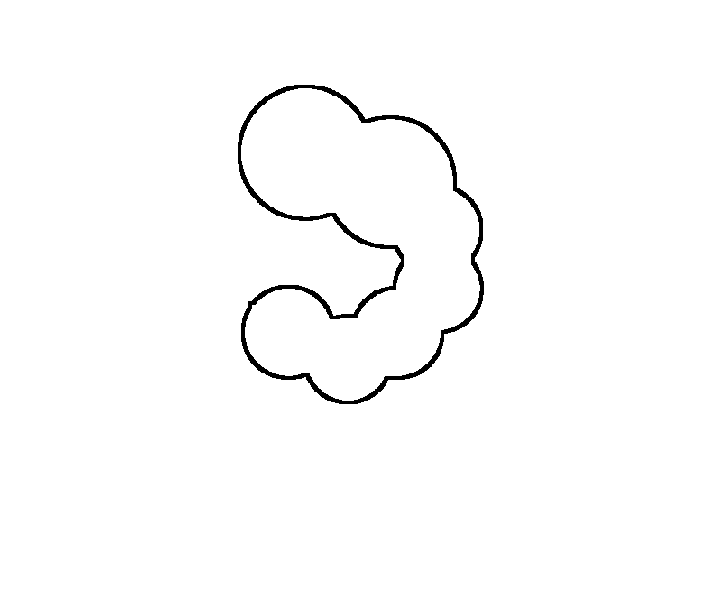


%Distancia del pixel al edge més proper
%Calculem primer l'edge
se = ones(5,5);
edge = imdilate(closing,se) - imerode(closing,se);
%Fem ara la distancia
dist = bwdist(edge);
imshow(dist);

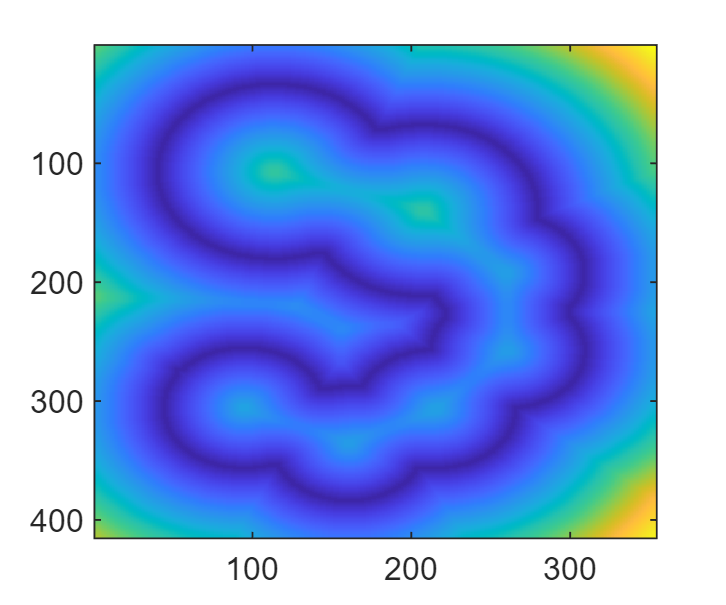


%Apliquem una dilatació (5,5)
se = ones(5,5);
dilatacio = imdilate(dist,se);
imagesc(dilatacio);

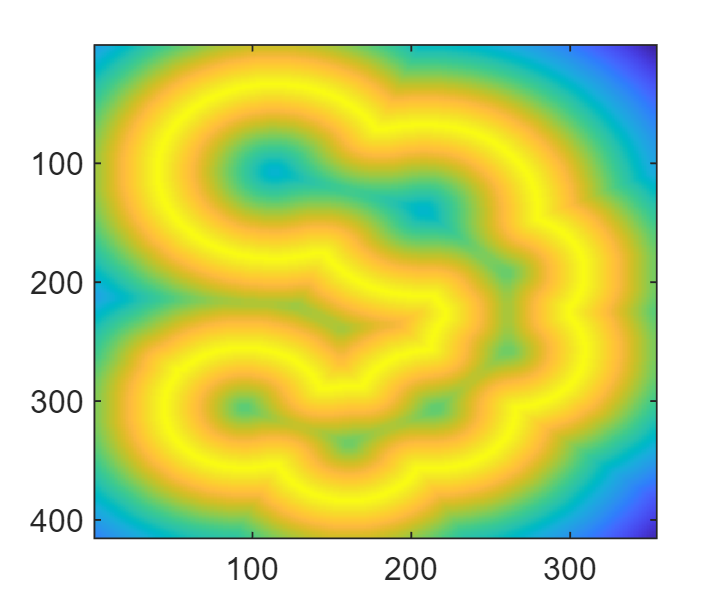


%Fem la inversa i apliquem watersheed. 
inv = 1 - dilatacio;
imagesc(inv);

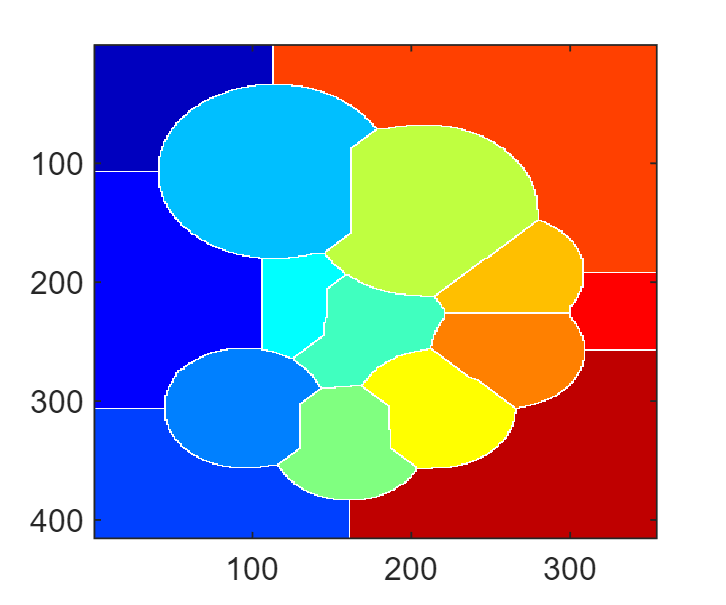

y = watershed(inv,8);
color = im2double(label2rgb(y));
imagesc(color);

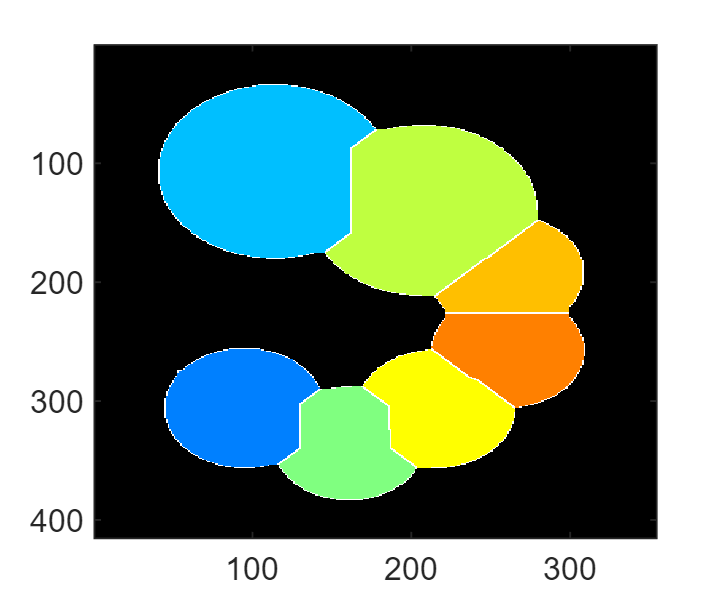


%Restringim el resultat als objectes d'interès
im5_final = closing.*color;
imagesc(im5_final);


%Contem les monedes que hem segmentat




